J=0.2

J = 0.2000

B=3

B = 3

K=250

K = 250

tau=0.001*50 % in second

tau = 0.0500

k_e=0

k_e = 0

b_e=0

b_e = 0

m_e=0%% .1

m_e = 0

P_t=50

P_t = 50

I_t=10

I_t = 10

I_m=0

I_m = 0

P_m=6

P_m = 6

w_ve=sqrt(J/B)

w_ve = 0.2582

w_co=sqrt(P_t/I_t)

w_co = 2.2361

eval(aa1)

ans = 9437500

eval(routh)

ans = 	1.0e+04 *

    0.0000    1.2750
    0.0003    0.2500
    1.2583         0
    0.2500         0


evalEffective

$$x = s$$

w =     0.0100    0.0102    0.0105    0.0107    0.0110    0.0112    0.0115    0.0118    0.0120    0.0123    0.0126    0.0129    0.0132    0.0135    0.0138    0.0141    0.0145    0.0148    0.0152    0.0155    0.0159    0.0162    0.0166    0.0170    0.0174    0.0178    0.0182    0.0186    0.0191    0.0195    0.0200    0.0205    0.0209    0.0214    0.0219    0.0224    0.0230    0.0235    0.0240    0.0246    0.0252    0.0258    0.0264    0.0270    0.0276    0.0283    0.0289    0.0296    0.0303    0.0310


$$s = w\,\mathrm{i}$$

im_pos_index =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10



im_neg_index =

  0×1 empty double column vector



re_pos_index =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10



ES =

     []


EM =

     []


ED =

     []



a = 1

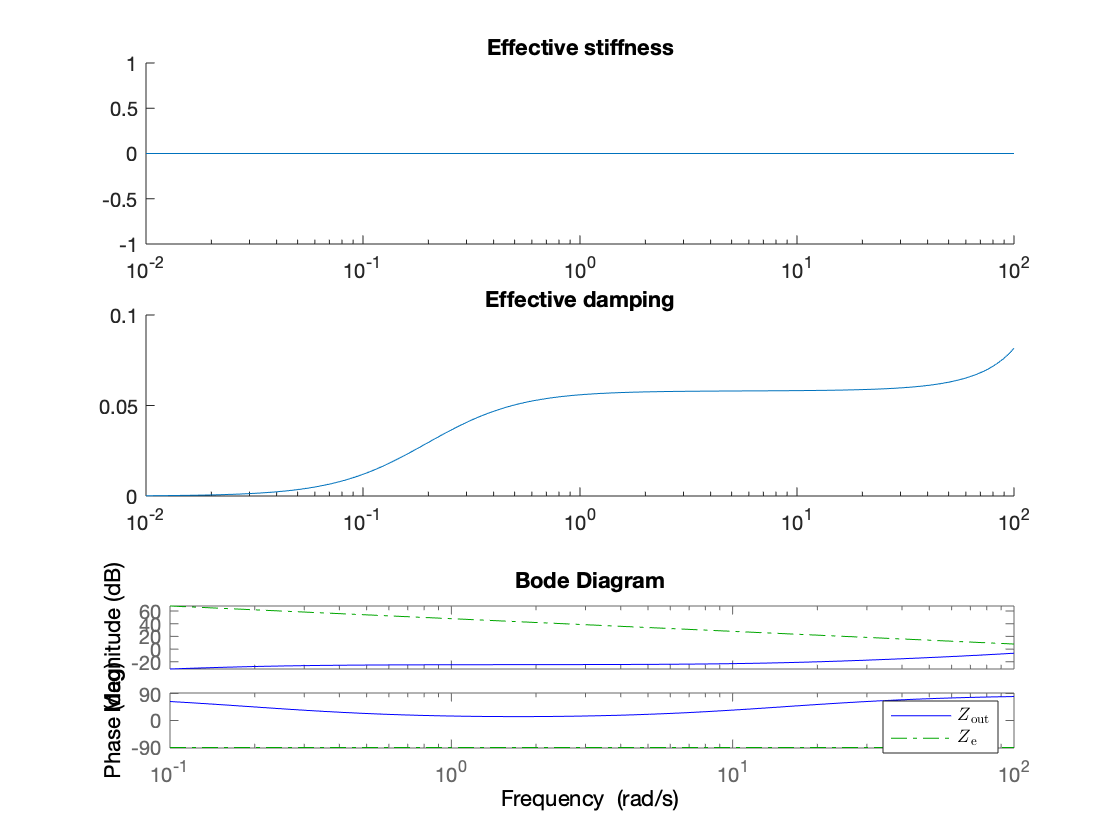


plotEffective

% m_e=1
% hold
% evalEffective
% plotEffective
% 
% m_e=1.5
% evalEffective
% plotEffective
% h = legend('$k\_{\mathrm{e}}=40$', '$k\_{\mathrm{e}}=80$', '$k\_{\mathrm{e}}=120$'); set(h, 'Interpreter', 'latex');
phy=tf([K],[1, 0]);
%env=tf([0 b_e*k_e],[b_e k_e]);
%env2=tf([K],[m_e 0 K])*env;
ze=tf([m_e 0 0],[b_e (k_e-K)])+tf([b_e k_e],[1 0]);%*tf([K],[1 0])%
clear s; 
syms s;
x=s;
[numa dena]=numden(eval(Z2));
numa=eval(fliplr(coeffs(numa,s)));
dena=eval(fliplr(coeffs(dena,s)));
%sys=tf(numa,[dena]); % maxwell
sys=tf([numa 0],[dena]); % null
% Normal below

bode(sys,'b-',phy,'g-.',{0.1,100}) 
%,env,'r--'

h = legend('$Z\_{\mathrm{out}}$', '$Z\_{\mathrm{e}}$', '$K/s$','$\omega_{\mathrm{ve}}$', '$\omega_{\mathrm{co}}$'); set(h, 'Interpreter', 'latex');


%h = legend('$Z\_{\mathrm{out}}$', '$Z\_{\mathrm{r}}$', '$K/s$','$\omega_{\mathrm{ve}}$', '$\omega_{\mathrm{co}}$'); set(h, 'Interpreter', 'latex');
